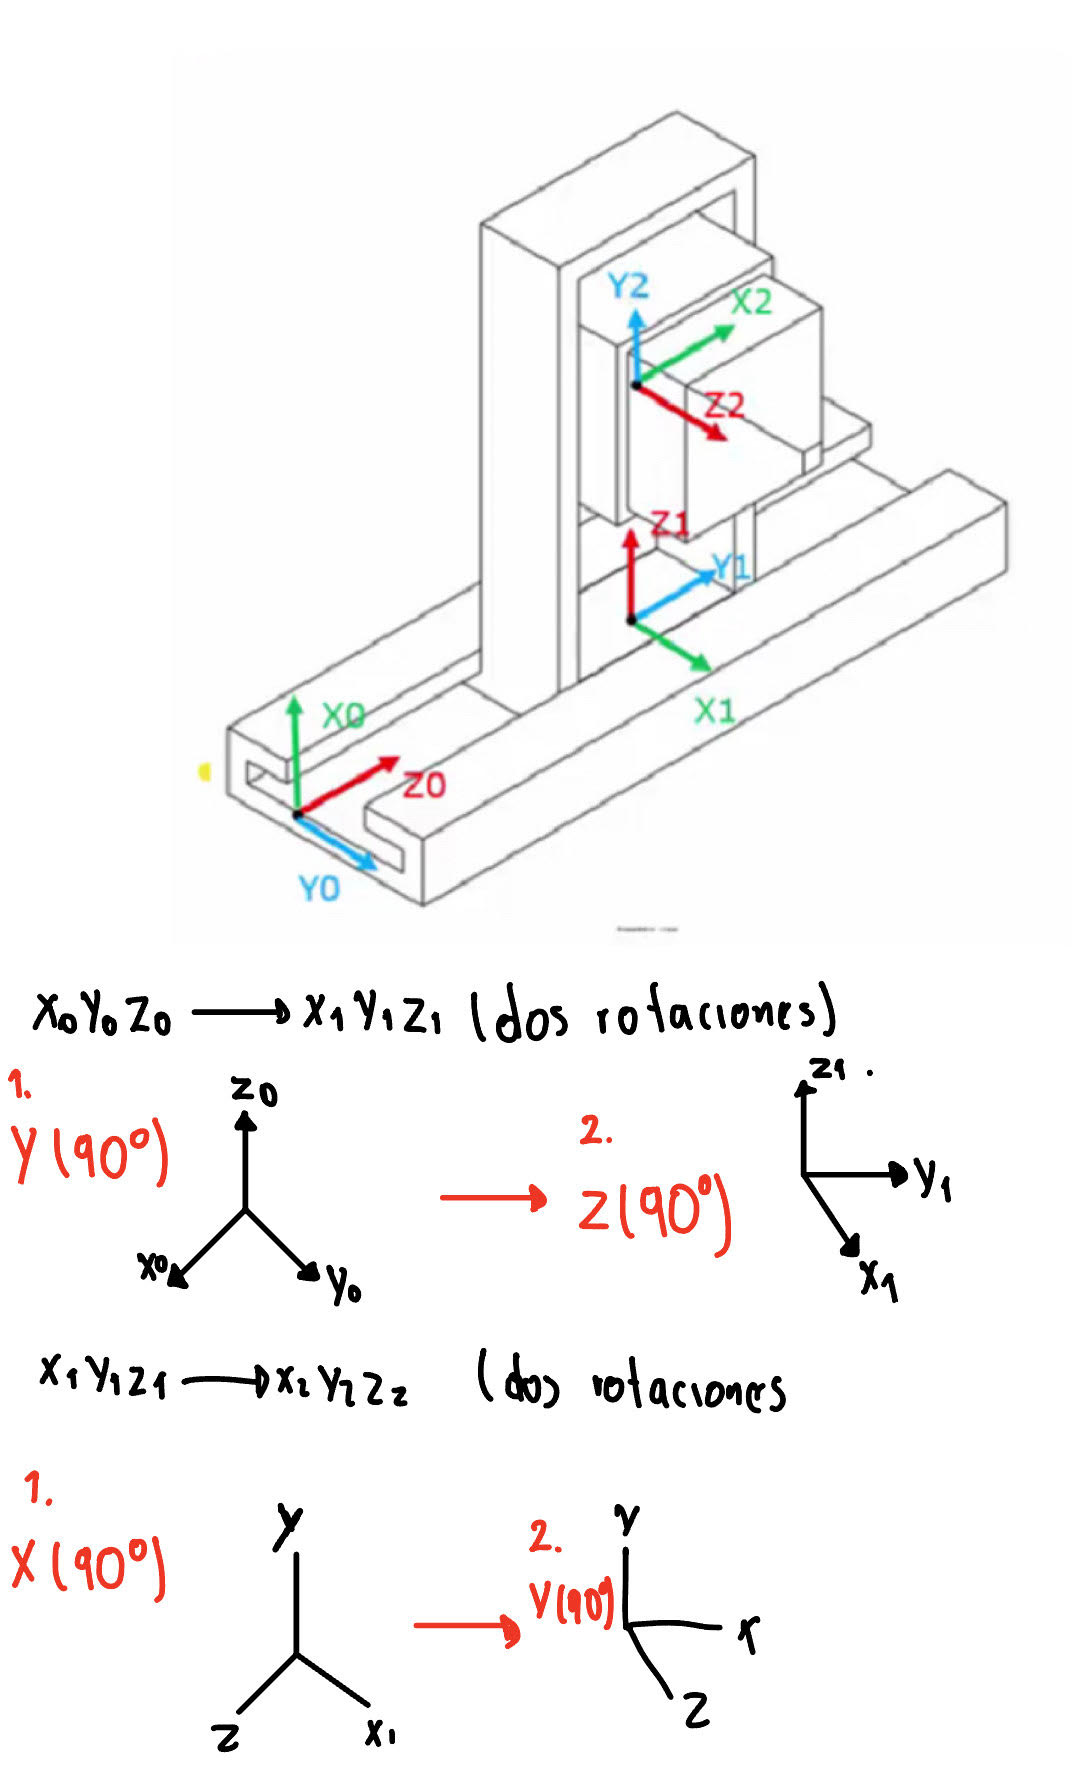

# **Actividad 4. Análisis Genera**

## Sección 1: Limpieza de entorno, variables simbólicas y configuración básica

Descripción:

- Se limpian las variables y las ventanas de MATLAB (`clear all`, `close all`, `clc`).

- Se declaran las variables simbólicas para las articulaciones (`th1`, `th2`, `th3`) y las longitudes (`l1`, `l2`, `l3`).

- Se especifica que el robot tiene tres juntas prismáticas (vector `RP=[1 1 1]`, donde 1 = junta prismática).

- Se crean los vectores de coordenadas articulares `Q` y sus velocidades `Qp`.

- Se determina el número de grados de libertad (`GDL`).

- Se definen las posiciones (`P`) y rotaciones (`R`) de cada articulación localmente, basadas en las distancias (`l1`, `l2`, `l3`) y las matrices de rotación en ángulos de 90°.

- Se utiliza la convención de que la primera articulación está a una distancia `l1` en el eje Z, la segunda a `l2` y la tercera a `l3`, con las rotaciones necesarias para que los ejes queden alineados según se requiera.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


## Sección 2: Salida en consola de las matrices de rotación

Descripción:

- Estas líneas muestran cómo se imprime en la ventana de comandos la información de las matrices de rotación `R(:,:,1)`, `R(:,:,2)` y `R(:,:,3)` definidas en la sección anterior.

- Observa que el resultado de `rotacion_y(90)*rotacion_z(90)` y similares se despliega en forma de matriz numérica.

%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= rotacion_y(90)*rotacion_z(90);

%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [0;0;l2];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)=  rotacion_x(90) * rotacion_y(90);

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0;0;l3];

%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=  eye(3);

## Sección 3: Construcción de las matrices de transformación homogénea (locales y globales)

Descripción:

- Se crea un vector de ceros `Vector_Zeros` para usar en la última fila de las matrices de transformación homogénea.

- Se inicializan las matrices de transformación locales `A` y globales `T`.

- Se definen `PO` y `RO` para almacenar la posición y la rotación global en cada paso.

- Dentro del bucle `for`, para cada articulación se construye la matriz `A(:,:,i)` (que combina la rotación `R(:,:,i)` y la traslación `P(:,:,i)`) y se multiplica con la matriz global previa `T(:,:,i-1)` para obtener la nueva transformación global `T(:,:,i)`.

- Se muestran en pantalla (con `disp` y `pretty`) las matrices de transformación global resultantes en cada iteración.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


## Sección 4: Visualización de las matrices de transformación global T1, T2 y T3

Descripción:

- Se despliega en la ventana de comandos la información de cada matriz de transformación global `T1`, `T2` y `T3`.

- El formato `pretty` permite ver la estructura de la matriz de forma simbólica, con las variables `l1`, `l2`, `l3`.

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 0, 1,  0 \
|             |
| 1, 0, 0,  0 |
|             |
| 0, 1, 0, l1 |
|             |
\ 0, 0, 0,  1 /



Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\\ 0 & 0 & 1 & 0\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 1, 0, l2 \
|             |
| 0, 0, 1,  0 |
|             |
| 1, 0, 0, l1 |
|             |
\ 0, 0, 0,  1 /



Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\\ 0 & 0 & 1 & 0\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\\ 0 & 0 & 1 & l_{3}\\ 1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ 0, 1, 0, l2 \
|             |
| 0, 0, 1, l3 |
|             |
| 1, 0, 0, l1 |
|             |
\ 0, 0, 0,  1 /



## Sección 5: Cálculo del Jacobiano lineal (diferencial y analítico)

Descripción:

- Se calculan las derivadas parciales de la posición final (`PO`) con respecto a cada variable articular (`th1`, `th2`, `th3`) usando `functionalDerivative`. Esto forma el Jacobiano lineal diferencial `jv_d`.

- Se define el Jacobiano lineal analítico `Jv_a` y el Jacobiano angular `Jw_a`.

- Dependiendo del tipo de articulación (rotacional o prismática), se determina cómo se calcula la contribución a la velocidad lineal (producto vectorial con el eje de rotación) y la velocidad angular (eje de rotación para las juntas rotacionales y cero para las prismáticas).

- Se simplifican `Jv_a` y `Jw_a` con la función `simplify`.


%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ _________ \
|  d        |
| -- th2(t) |
| dt        |
|           |
| _________ |
|  d        |
| -- th3(t) |
| dt        |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


## Sección 6: Obtención de la velocidad lineal y angular del efector

Descripción:

- Se multiplican los Jacobianos por el vector de velocidades articulares `Qp'` para hallar la velocidad lineal `V` y la velocidad angular `W`.

- Con `pretty(V)` y `pretty(W)` se muestran las expresiones simbólicas resultantes.

- Se observa que la velocidad angular es cero, lo que indica que en esta configuración de robot prismático (o con las rotaciones definidas) no hay componente angular.

W=simplify (Jw_a*Qp');
    pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



disp(W);

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Sección 7: Funciones auxiliares de rotación

Descripción:

- Se definen tres funciones (`rotacion_x`, `rotacion_y`, `rotacion_z`) que retornan matrices de rotación en 3D, usando funciones trigonométricas en grados (`cosd`, `sind`).

- Estas funciones permiten construir las matrices homogéneas en los pasos anteriores, aplicando las rotaciones correspondientes alrededor de los ejes X, Y y Z.

%funciones auxiliares para rotaciones
function Rx = rotacion_x(theta)
   
    Rx = [1,         0,           0;
          0, cosd(theta), -sind(theta);
          0, sind(theta),  cosd(theta)];
end


function Ry = rotacion_y(theta)
    % ROTACION_Y - Matriz de rotación alrededor del eje Y
    Ry = [ cosd(theta), 0, sind(theta);
                  0, 1,          0;
          -sind(theta), 0, cosd(theta)];
end

function Rz = rotacion_z(theta)
    % ROTACION_Z - Matriz de rotación alrededor del eje Z
    Rz = [cosd(theta), -sind(theta), 0;
          sind(theta),  cosd(theta), 0;
                 0,            0, 1];
end

**Analisis final:**

En este robot de 3 GDL configurado con juntas prismáticas, cada articulación introduce un desplazamiento lineal sin generar rotación. Por ello, al multiplicar el Jacobiano lineal por las velocidades articulares (Q˙�), se obtiene una velocidad lineal cuyo valor depende directamente de las derivadas de esos desplazamientos, y la velocidad angular aparece como cero en cada componente.

En términos más concretos:

- Velocidad lineal (V):Se compone de las derivadas de los desplazamientos prismáticos. Cada junta prismática contribuye a la posición final del efector, por lo que la velocidad lineal resultante es la suma (vectorial) de esas aportaciones.

- Velocidad angular (W):Dado que no existen juntas rotacionales (0 en el vector `RP`), no hay ningún eje de rotación que genere cambio angular. Por ello, la matriz Jacobiana angular se llena de ceros, y al multiplicarla por Q˙� (las velocidades de las juntas prismáticas), se obtiene W=0.

Esta es la razón fundamental de por qué, en un robot puramente prismático, la velocidad lineal del efector depende exclusivamente de las variaciones de las longitudes de las juntas, mientras que la velocidad angular es nula.